依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

PCA, leant, transfer, final 比较。

预加载此脚本一次即可

[~,Score]=TransferLearning.UnifiedPcaModel(Paradigm="光声");

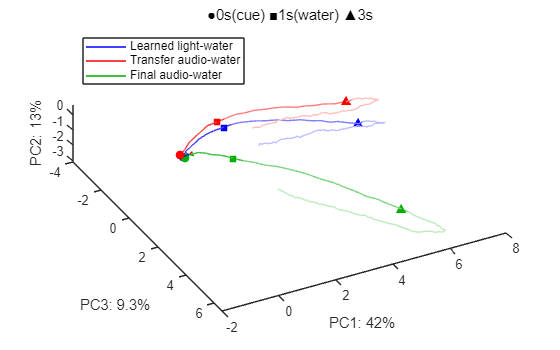

PCs=[3,1,2];
LinesPC=table;
LinesPC.Points=permute(Score.Score{PCs,:,["Learned","Transfer","Final"]},[3,1,2]);
LinesPC.Color=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Markers=table;
Markers.Index=[24;32;48];
Markers.Shape=('os^')';
Fig=figure;
Lines=UniExp.SegmentFadePlot(LinesPC,Markers);
Explained=Score.Explained(PCs);
UniExp.PcAxLabels(table(PCs',Explained,'VariableNames',["Index","Explained"],'RowNames',["X";"Y";"Z"]));
L=legend(Lines,["Learned light-water","Transfer audio-water","Final audio-water"],Location='northwest');
title('●0s(cue) ■1s(water) ▲3s');
view(90*(1-Explained(1)*2/(Explained(1)*2+Explained(2))),90*(1-Explained(3)/sum(Explained)));
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('Fig2D.png'),'-dpng','-r400');